# Ejercicio 4 (2,25 puntos). Respuesta temporal de sistemas de control. Parámetros característicos. 

### Construye cuatro sistemas de control cuyas funciones de transferencia G1, G2, G3 y G4 no tengan ceros, tengan un par de polos complejos conjugados en s=-5±4j, y además:

### • G1 tenga un polo adicional en s=-2, y una ganancia estática igual a 200.

G1 = zpk([], [-2 -5+4i -5-4i], 200)

G1 =
 
           200
  ----------------------
  (s+2) (s^2 + 10s + 41)
 
Continuous-time zero/pole/gain model.
Model Properties


### • G2 tenga un polo adicional en s=-5, y una ganancia estática igual a 500.

G2 = zpk([], [-5 -5+4i -5-4i], 500)

G2 =
 
           500
  ----------------------
  (s+5) (s^2 + 10s + 41)
 
Continuous-time zero/pole/gain model.
Model Properties


### • G3 tenga un polo adicional en s=-10, y una ganancia estática igual a 1000.

G3 = zpk([], [-10 -5+4i -5-4i], 1000)

G3 =
 
           1000
  -----------------------
  (s+10) (s^2 + 10s + 41)
 
Continuous-time zero/pole/gain model.
Model Properties


### • G4 tenga un polo adicional en s=-100, y una ganancia estática igual a 10000.

G4 = zpk([], [-100 -5+4i -5-4i], 10000)

G4 =
 
           10000
  ------------------------
  (s+100) (s^2 + 10s + 41)
 
Continuous-time zero/pole/gain model.
Model Properties


### Para todas ellas:

### a) Realiza una gráfica de la respuesta de los cuatro sistemas ante una entrada impulso unitario. (todas en la misma gráfica).

figure;
impulse(G1, G2, G3, G4);

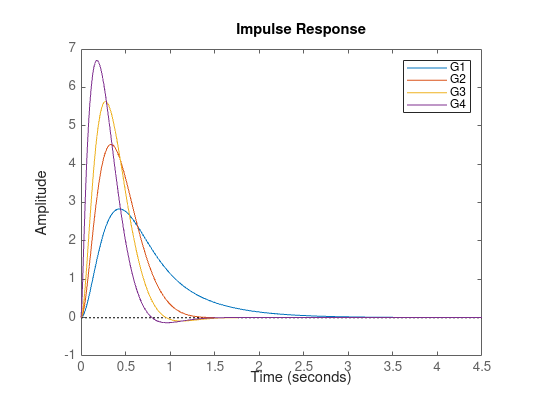

legend('G1', 'G2', 'G3', 'G4')

### b) Ídem, para una entrada escalón de amplitud igual a 2 (todas en otra gráfica diferente).

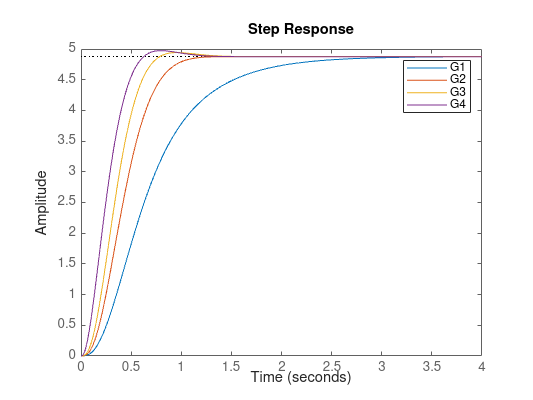

figure;
step(2*G1, 2*G2, 2*G3, 2*G4);
legend('G1', 'G2', 'G3', 'G4');

### c) Ídem, para una entrada rampa de pendiente igual a 3 (todas en otra gráfica diferente).

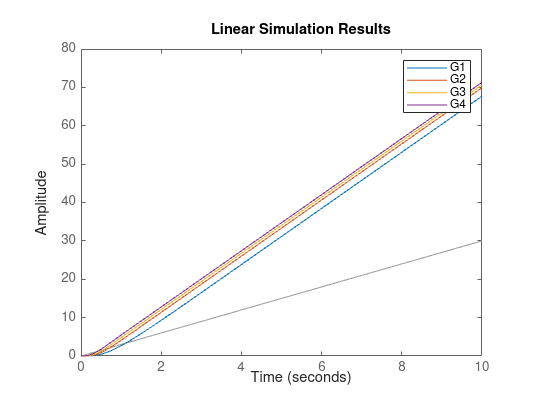

t=linspace(0,10,100);
rampa=3*t;
figure;
lsim(G1,G2,G3,G4,rampa,t);
legend('G1', 'G2', 'G3', 'G4'); 

### d) Basándote en las respuestas al escalón, indica y justifica el tipo de cada una de las respuestas temporales (oscilatoria, subamortiguada, con amortiguamiento crítico o sobreamortiguada).

%Primero hay que tener en cuenta que todos que originalmente
%todos eran una funcion de transferencia de grado 2, a la
%cual podemos calcularle el coeficiente de amortiguamiento
G=zpk([],[-5+4i, -5-4i],1)

G =
 
         1
  ----------------
  (s^2 + 10s + 41)
 
Continuous-time zero/pole/gain model.
Model Properties


wn=sqrt(41)

wn = 6.4031

damp=10/(2*wn)

damp = 0.7809

Como podemos ver, incialmente el sistema tenía un coeficiente de amortiguamiento igual a 0.7809, lo que significa, que era un sistema subamortiguado con muchas oscilaciones

Cuando añadimos polos que están muy cercas del sistema, este lo ralentiza bastante, pero si lo ponemos muy lejos, es como no estuviera.

Para ello, podemos utilizar el teorema del valor final, que nos indicará hacia que valores debería estabilizarse la entrada. De esa forma, podemos determinar visualmente que sistema es y luego analizarlo

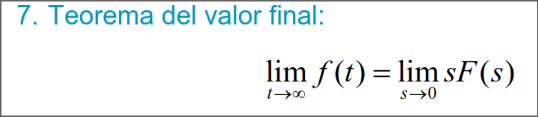

%Para ello resolvemos el límite
syms s;
%Fs = Xs * Gs
%Xs = 1/s ya que estamos analizando entrada de escalón
%Al estar calculando el limite con entrada escalón, la s de la función se
%cancela con el 2/s de la entrada, de tal forma que solo tendremos que
%multiplicar cada funcion x2 y analizar el limite
%Sin embargo, matlab no acepta como limite funciones en formato de funcion
%de transferencia, así que hay que reescribirlos manualmente

sFs1 = 2*(200/((s+2)*(s^2+10*s+41)))

$$sFs1 = \frac{400}{\left(s+2\right)\,\left(s^{2}+10\,s+41\right)}$$

ft1 = limit(sFs1,s,0)

$$ft1 = \frac{200}{41}$$



sFs2 = 2*(500/((s+5)*(s^2+10*s+41)))

$$sFs2 = \frac{1000}{\left(s+5\right)\,\left(s^{2}+10\,s+41\right)}$$

ft2 = limit(sFs2,s,0)

$$ft2 = \frac{200}{41}$$



sFs3 = 2*(1000/((s+10)*(s^2+10*s+41)))

$$sFs3 = \frac{2000}{\left(s+10\right)\,\left(s^{2}+10\,s+41\right)}$$

ft3 = limit(sFs3,s,0)

$$ft3 = \frac{200}{41}$$


sFs4 = 2*(10000/((s+100)*(s^2+10*s+41)))

$$sFs4 = \frac{20000}{\left(s+100\right)\,\left(s^{2}+10\,s+41\right)}$$

ft4 = limit(sFs4,s,0)

$$ft4 = \frac{200}{41}$$


approx = vpa(ft1)

$$approx = 4.8780487804878048780487804878049$$

En este caso, podemos ver que todos tienden a estabilizarse aproximamente para 4.87

Entonces, visualmente podemos darnos cuenta que

->G1 es sobreamortiguada

->G2 es criticamente amortiguada

->G3 y G4 subamortiguadas

G1 es sobreamortiguada ya que añadimos un polo muy cercano al eje imaginario, es decir, un polo tan lento que le quita las oscilasciones al sistema original.

G2, al tener un polo ligeremante cercano a los polos imaginarios del sistema, pero sin estar tan cerca del eje imaginario,consigue el mejor escenario posible, acelerar el sistema y quitar las oscilaciones

A partir de aquí, podemos ver que añadir cualquier polo mayor que -5, estará suficientemente lejos del sistema que no lo afectará mucho. Es por eso que G3 sobreoscila, al ser un polo rápido no consigue quitarle las oscilasciones al sistema. Luego con G4, al tener un polo tan lejano, ni siquiera afecta al sistema, es como si no estuviese el polo. Y precisamente estas dos funciones mantienen oscilaciones, ya que el sistema original, era subamortiguado.

### e) Extrae numéricamente su tiempo de subida, tiempo de asentamiento, sobreelongación, y tiempo de pico (cuando sea posible) y valor final en estado estacionario frente a la entrada escalón de amplitud igual a 2. Indica cuáles de ellas se verían afectadas si el escalón hubiera sido de amplitud igual a 5.

G1_info = stepinfo(2*G1)

G1_info = struct with fields:
         RiseTime: 1.1460
    TransientTime: 2.2037
     SettlingTime: 2.2037
      SettlingMin: 4.3938
      SettlingMax: 4.8763
        Overshoot: 0
       Undershoot: 0
             Peak: 4.8763
         PeakTime: 4.2183


G2_info = stepinfo(2*G2);
G3_info = stepinfo(2*G3);
G4_info = stepinfo(2*G4);
tr1 = G1_info.RiseTime

tr1 = 1.1460

ts1 = G1_info.SettlingTime

ts1 = 2.2037

Mp1 = G1_info.Overshoot

Mp1 = 0

tp1 = G1_info.PeakTime

tp1 = 4.2183

tr2 = G2_info.RiseTime

tr2 = 0.5719

ts2 = G2_info.SettlingTime

ts2 = 0.9852

Mp2 = G2_info.Overshoot

Mp2 = 0

tp2 = G2_info.PeakTime

tp2 = 1.6487

tr3 = G3_info.RiseTime

tr3 = 0.4405

ts3 = G3_info.SettlingTime

ts3 = 0.7157

Mp3 = G3_info.Overshoot

Mp3 = 1.3166

tp3 = G3_info.PeakTime

tp3 = 0.9579

tr4 = G4_info.RiseTime

tr4 = 0.3751

ts4 = G4_info.SettlingTime

ts4 = 0.5744

Mp4 = G4_info.Overshoot

Mp4 = 1.9654

tp4 = G4_info.PeakTime

tp4 = 0.7921

### f) Para los cuatro sistemas de control, ¿en qué casos se puede utilizar la aproximación mediante polos dominantes? ¿Qué polos dominantes tendrían los sistemas en cada caso, y por qué? Justifica detalladamente tu respuesta en base a las gráficas y a los valores numéricos extraídos. Puedes realizar gráficas adicionales si te sirven para la justificación.

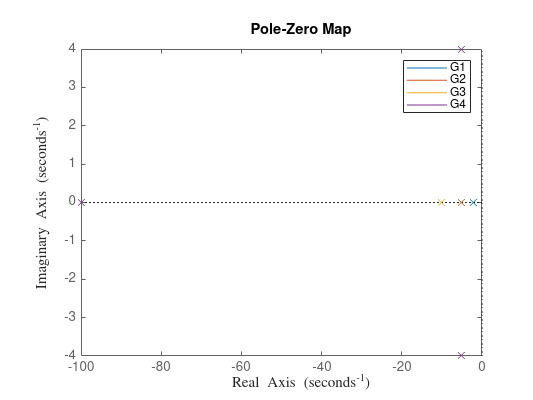

%Dibujo los polos y ceros de las FT:
figure; hold on
pzmap(G1, G2, G3, G4);
legend('G1', 'G2', 'G3', 'G4'); hold off